# MATLAB - COMSOL Livelink Pipeline AI Surrogate 

Data export from COMSOL for CNN for AI surrogate of FEM models. 

Import COMSOL and paths.

## Inputs of the FEM model.

%dielectric properties
fat = readtable('fat.txt');
skin = readtable('skin.txt');
muscle = readtable('muscle.txt');
nerve = readtable('nerve.txt');
bone = readtable('bone.txt');

Oversamplig Frequency

tables = {'fat', 'skin', 'muscle', 'nerve', 'bone'};

%iterate tables and oversample frequency

for i = 1:length(tables)

    current_table = eval(tables{i});
    
    frequency = current_table{:, 'FrequencyHz'};
    permittivity = current_table{:, 'Permittivity'};
    elec_cond = current_table{:, 'Elec_Cond__S_m_'};
    
    new_frequency = (min(frequency):1:max(frequency))';
    
    new_permittivity = interp1(frequency, permittivity, new_frequency, 'linear');
    new_elec_cond = interp1(frequency, elec_cond, new_frequency, 'linear');
    
    new_table = table(new_frequency, new_permittivity, new_elec_cond, ...
        'VariableNames', {'FrequencyHz', 'Permittivity', 'Elec__Cond_S_m_'});
    %delete old frequency and save oversampled
    clear(tables{i}); 
    assignin('base', tables{i}, new_table); 

end

clear current_table i new_elec_cond new_table new_permittivity new_frequency frequency elec_cond permittivity

## Concentric Electrodes

This part of the code runs COMSOL simulations for the Concentric electrode designs. Pipeline:

- Load the COMSOL model and define output directions

- Read the spreadsheet file with the concentric electrode designs

- Define the range of current and apply dielectric properties to the model

- Iterate the designs of concentric electrodes and iterate each design with the current range 

Parameters of the concentric geometry in cm: 

- central: central electrode radius

- inner: ring inner radius

- outer: ring outer radius

import com.comsol.model.*
import com.comsol.model.util.*

path_to_model = ' ';

model = mphopen(path_to_model)

output_dir = ' ';
if ~exist(output_dir, 'dir')
    mkdir(output_dir); 
end
output_txt =' '
if ~exist(output_txt, 'dir')
    mkdir(output_txt);  
end

Read values from spreadsheets

%Read spreadsheets
filename = ' '
data = readtable(filename, 'Sheet',1);


model =

COMSOL Model Object
Name: thigh_test_concentric.mph
Tag: Model
Identifier: root




%Variables
central_values = data{:, 2}/2; % /2 for radius
inner_values =  data{:, 3}; 
outer_values =  data{:, 4}; 
key = string(data{:,1});

output_txt = 'E:\AI surrogate\1D_concentric_geometries_v4\'

nerve_depths = data{:,12};
I_stim_values = data{:,9};
pulse = data{:,20};
one_out = string(data{:,15});

%Output values
num_dofs = zeros(length(central_values), 1);

filename = 'v5 experiment details.xlsx'

num_elements = [0,0,0,0];

time_comsol = zeros(length(key), 1);


Configuration of the model - Frequency

% Apply dielectric properties to the model according to the frequency
frequency = bone.FrequencyHz;

frequency_value = 50;  
tables = {'skin', 'fat', 'muscle', 'bone', 'nerve'};
perm_var_names = {'skin_p', 'fat_p', 'muscle_p', 'bone_p', 'nerve_p'};
cond_var_names = {'skin_c', 'fat_c', 'muscle_c', 'bone_c', 'nerve_c'};

for t = 1:length(tables)
        fprintf('Parameters for = %.1f Hz\n', frequency(frequency_value));
        current_table = eval(tables{t});
        permittivity = current_table.Permittivity(frequency_value);
        elec_cond = current_table.Elec__Cond_S_m_(frequency_value);
        model.param.set(perm_var_names{t}, permittivity);
        model.param.set(cond_var_names{t}, elec_cond);

        fprintf('  %s -> Permittivity: %.2e, Conductivity: %.2e\n', tables{t}, permittivity, elec_cond);
end

Run Simulation


for j = 1:length(central_values)
    tic; % Iniciate timer
    model.param.set('central', central_values(j)); 
    model.param.set('inner', inner_values(j));  
    model.param.set('outer', outer_values(j));
    model.param.set('pos_nerve', nerve_depths(j));  
    model.geom('geom1').run();  % Update geometry
    model.mesh('mesh1').run();  % Generate mesh
    model.param.set('I_stim', sprintf('%g[mA]', I_stim_values(j)));  % Update current
    model.study('std1').run();  % Solve the study

    info = mphxmeshinfo(model);
    num_dofs(j) = info.ndofs; % Extract DOFs



Parametros para frecuencia = 50.0 Hz


  skin -> Permittivity: 1.14e+03, Conductivity: 2.00e-04


Parametros para frecuencia = 50.0 Hz


  fat -> Permittivity: 4.58e+05, Conductivity: 4.04e-02


Parametros para frecuencia = 50.0 Hz


  muscle -> Permittivity: 1.77e+07, Conductivity: 2.33e-01


Parametros para frecuencia = 50.0 Hz


  bone -> Permittivity: 8.87e+03, Conductivity: 2.01e-02


Parametros para frecuencia = 50.0 Hz


  nerve -> Permittivity: 1.61e+06, Conductivity: 2.74e-02


    % Configuration of the voltage plot
    color_min = 0;  
    color_max = 1000;
    model.result('pg3').feature('surf1').set('rangecoloractive', true);
    model.result('pg3').feature('surf1').set('rangecolormin', color_min);
    model.result('pg3').feature('surf1').set('rangecolormax', color_max);
    model.result('pg3').run();

    % Export images and data
    % 2D image .png
    nombre_archivo_img = sprintf('%s/%s.png', output_dir, key(j));
    model.result.export('img1').set('filename', nombre_archivo_img);
    model.result.export('img1').run();

    % 2D values .csv
    txt_file_name1 = sprintf('%s/2D_%s.csv', output_dir, key(j));
    model.result.export('data1').set('filename', txt_file_name1);
    model.result.export('data1').set('header', false);
    model.result.export('data1').run();

    % 1D values .txt
    txt_file_name2 = sprintf('%s/1D_%s.txt', output_txt, key(j));
    model.result.export('data2').set('filename', txt_file_name2);
    model.result.export('data2').set('header', false);
    model.result.export('data2').run();

    % 1D values .csv
    txt_file_name4 = sprintf('%s/1D_%s.csv', output_dir, key(j));
    model.result.export('data2').set('filename', txt_file_name4);
    model.result.export('data2').set('header', false);
    model.result.export('data2').run();

    % 3D values .csv
    txt_file_name3 = sprintf('%s/3D_%s.csv', output_dir, key(j));
    model.result.export('data3').set('filename', txt_file_name3);
    model.result.export('data3').set('header', false);
    model.result.export('data3').run();

    fprintf('Results for: Key = %s exported correctly.\n', key(j));
    time_comsol(j) = toc;
    % Save values
    writematrix(time_comsol,'time_comsol', 'Delimiter', ',');
    writematrix(num_dofs,'num_dofs', 'Delimiter', ',');
end



MRG model

Parameters

dur = 2; 
V_fe = 1;
V_applied = 1;
stim_start = 0.1;
graphics = 0;

%Output variables
act_results = zeros(length(key),1);
time_mrg = zeros(length(key),1);
out = " " % output directory with 1D values

Run MRG model and detect activation

for j = 1:length(key)
    tic;
    stim_end = pulse(j)/1000 + stim_start; %pulse width
    file = sprintf('%s%s.txt',out,one_out(j)); %name of the 1D file with the voltage
    image = sprintf('%sMRG_%s.png',output_dir,key(j)); %image of the axon response


Resultados para: Key = TC2556 exportados correctamente.


    %Run MRG
    [ t,Y, N_nodes ] = mcintyre_final_1(dur, file, V_fe, V_applied, stim_start, stim_end, graphics);
    
    % Create graphic of MRG response
    pot_3D_v2(t,Y,N_nodes,1,image);

    %Detect activation 0/1
    b = detect_AP(Y,t,N_nodes,0);
    act_results(j) = b;

    %Record time
    time_mrg(j) = toc;
    %Extract extracelullar voltage in time
    mrg_mat = Y(:,1:N_nodes);
    %Save values

out = "E:\AI surrogate\1D_concentric_geometries_v4\"

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

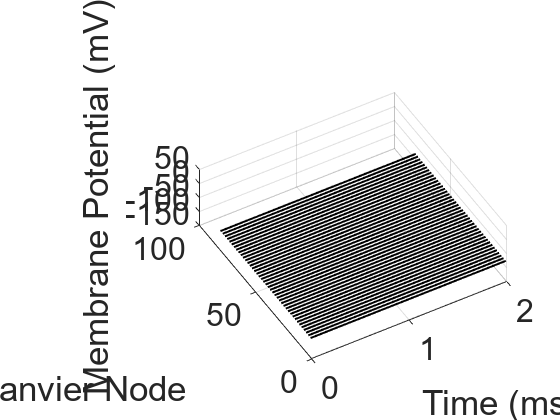

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 81
Percentage of activation: 0.00%


N = 81

dt = 0.1000

dt = 0.2000

image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5663.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5664.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5665.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5666.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5667.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5668.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5669.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5670.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5671.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5672.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5673.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5674.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5675.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5676.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5677.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5678.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5679.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5680.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5681.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5682.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5683.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5684.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5685.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5686.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5687.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5688.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5689.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5690.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5691.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5692.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5693.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5694.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5695.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5696.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5697.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5698.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5699.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

dt = 2.2000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5700.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5701.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5702.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5703.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5704.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5705.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5706.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5707.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5708.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

dt = 2.2000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5709.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5710.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5711.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5712.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5713.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5714.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5715.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5716.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5717.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5718.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5719.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5720.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5721.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5722.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5723.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5724.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5725.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5726.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5727.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5728.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5729.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5730.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5731.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5732.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5733.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5734.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5735.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5736.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5737.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5738.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5739.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5740.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5741.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5742.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5743.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5744.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

dt = 2.0000

dt = 2.1000

Total activated nodes: 0 / 80
Percentage of activation: 0.00%


image = 'E:\AI surrogate\concentric_geometries_v4\MRG_TC5745.png'

N = 80

dt = 0.1000

dt = 0.2000

dt = 0.3000

dt = 0.4000

dt = 0.5000

dt = 0.6000

dt = 0.7000

dt = 0.8000

dt = 0.9000

dt = 1.0000

dt = 1.1000

dt = 1.2000

dt = 1.3000

dt = 1.4000

dt = 1.5000

dt = 1.6000

dt = 1.7000

dt = 1.8000

dt = 1.9000

    matrix = sprintf('%sV_MRG_%s.csv',output_dir,key(j));
    writematrix(mrg_mat, matrix, 'Delimiter', ',');
    writematrix(time_mrg,'time_mrg','Delimiter',',');
    writematrix(act_results,'act_results','Delimiter',',');
end


